# Receiver Operator Characterisitc (ROC): Classifier Performance

We wish to evaluate a diagnotic test that classifies patients as either with disease (positive) or healthy (negative). When evaluating the test, we use a *reference standard. *The ROC curve is a mechanism for evaluating the new test. This notebook takes a look at what lies behind the ROC curve, how to plot informative figures and examine confidence intervals. 

% Set up the simulation

% Mean test scores for true positive cases and true negative cases
meanTestPositive = 20 ;
meanTestNegative = 10 ;

% Standard deviations of test scores 
stdTestPositive = 8 ;
stdTestNegative = 5 ;

% Size of sample
numSubjects = 150 ;

% Prevalence: the percentage of the total that are positive
prevalencePercent = 20 ;

% Number of subjects truly positive and negative
numPositive = round( prevalencePercent/100 * numSubjects ) ;
numNegative = numSubjects - numPositive ;

% Assign codes (numeric labels) for true positive and negative classes
posClass = +1 ; negClass = -1 ;

Now simulate the test scores. 

% randn draws from a normal distribution with zero mean and std of 1.
% randn([numPositive 1]) returns a column vector with numPositive values
% multiply by required std and add the required mean
scoresOfTruePositives = ( randn([numPositive 1]) * stdTestPositive ) + meanTestPositive ;
scoresOfTrueNegatives = ( randn([numNegative 1]) * stdTestNegative ) + meanTestNegative ;

% Assign subject number to a score
subjectNumbers = [1:numSubjects]' ; % list [1, 2, 3, ... numSubjects]
p = randperm(numSubjects) ;  % determine a random order of the subjects
subjectNumbers = subjectNumbers(p) ;

scoresTest = cat(1, scoresOfTruePositives, scoresOfTrueNegatives ) ; % concatenate scores
scoresTest = scoresTest(p) ; % apply the random order determined above

referenceStandard = cat(1, repmat(posClass,[numPositive 1]), repmat(negClass, [numNegative 1])) ; 
referenceStandard = referenceStandard(p) ;

refColours = cat(1, repmat([1 0 0],[numPositive 1]), repmat([0 0 1],[numNegative 1])) ;
refColours = refColours(p,:) ;

Before doing any numerical analysis, it is very useful to visualise your data. A simple thing is to just plot the scores using a scatter plot.

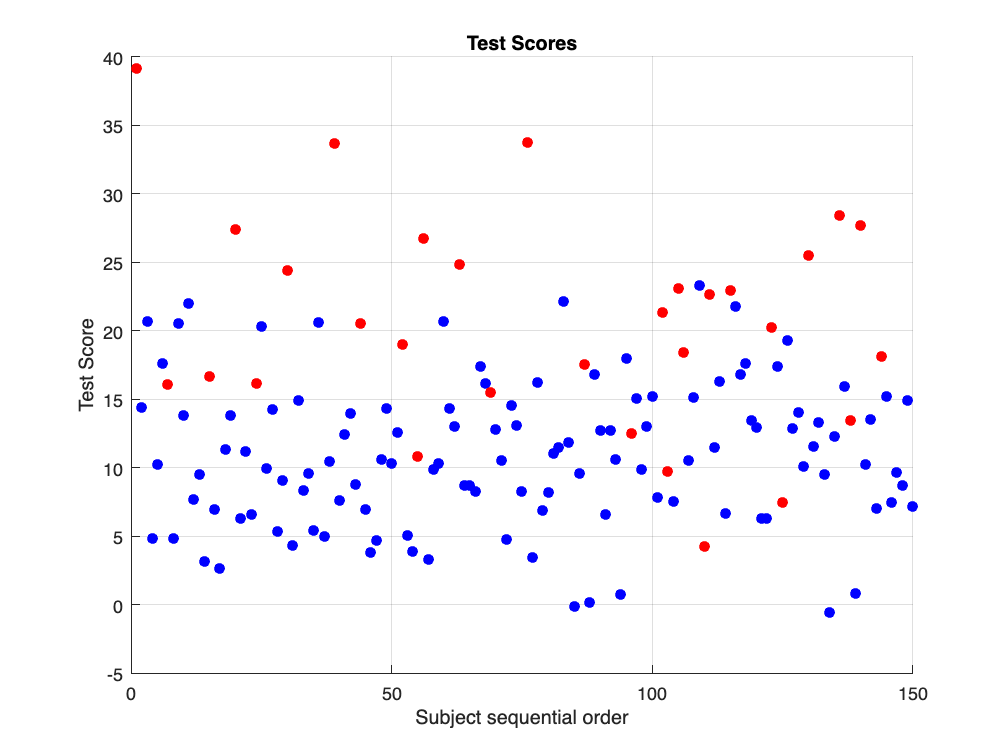

% Plot the values
figure(Name="Data Points")
scatter(1:numSubjects, scoresTest, [], refColours,"filled")
grid on
xlabel('Subject sequential order'), ylabel('Test Score')
title('Test Scores')

The scatter plot gives a good idea of the means and spreads, but is a bit cluttered. 

Alternativly, use a `swarmchart`. This offers a cleaner representation. Ideally we want the Test Scores for all the red positives to be well above the scores for the blue negatives. If that were the case, we could choose a Test Score value between the two groups as the threshold operating point. All scores above would be positives, and all below would be negatives. In reality, there is usually overlap and the `swarmchart` visualises how many points are in the overlapping region and a guide to the distributions. 

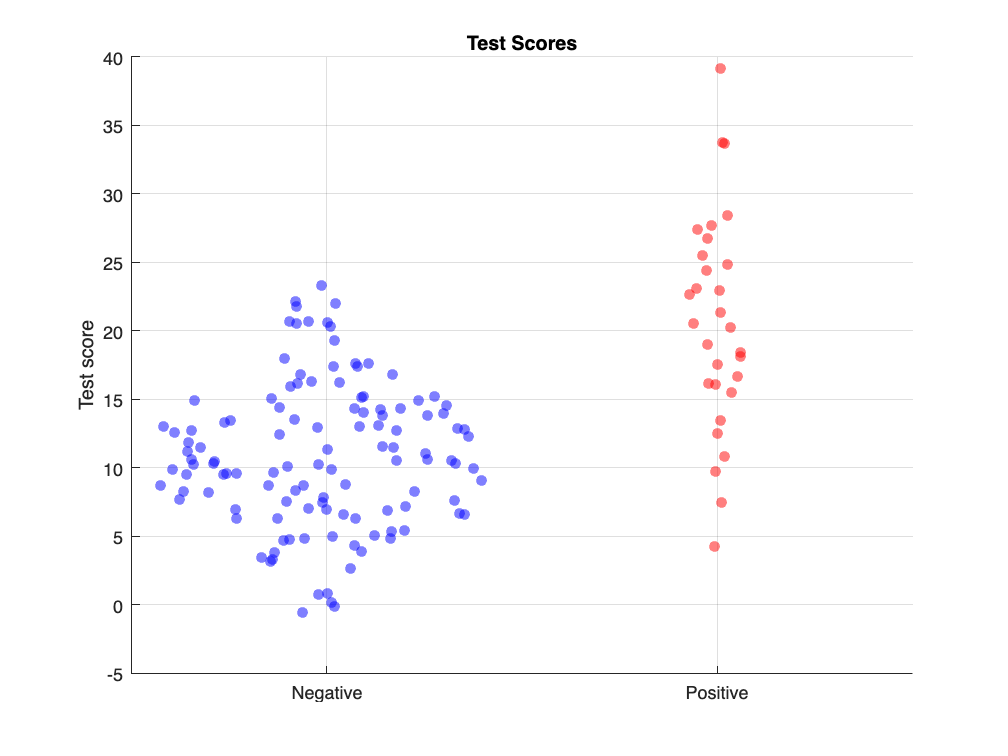

figure(Name='Test Scores')
swarmchart(referenceStandard, scoresTest, [], refColours, 'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
title('Test Scores')
ylabel('Test score')
xticks([negClass posClass]), xticklabels({'Negative','Positive'})
grid on

It is also common to see box and whisker plots. These have the advantage of showing values such as median and interquartile range. They don't provide a very good representation of the overlap region, compared to the `swarmchart` above, or histograms below.

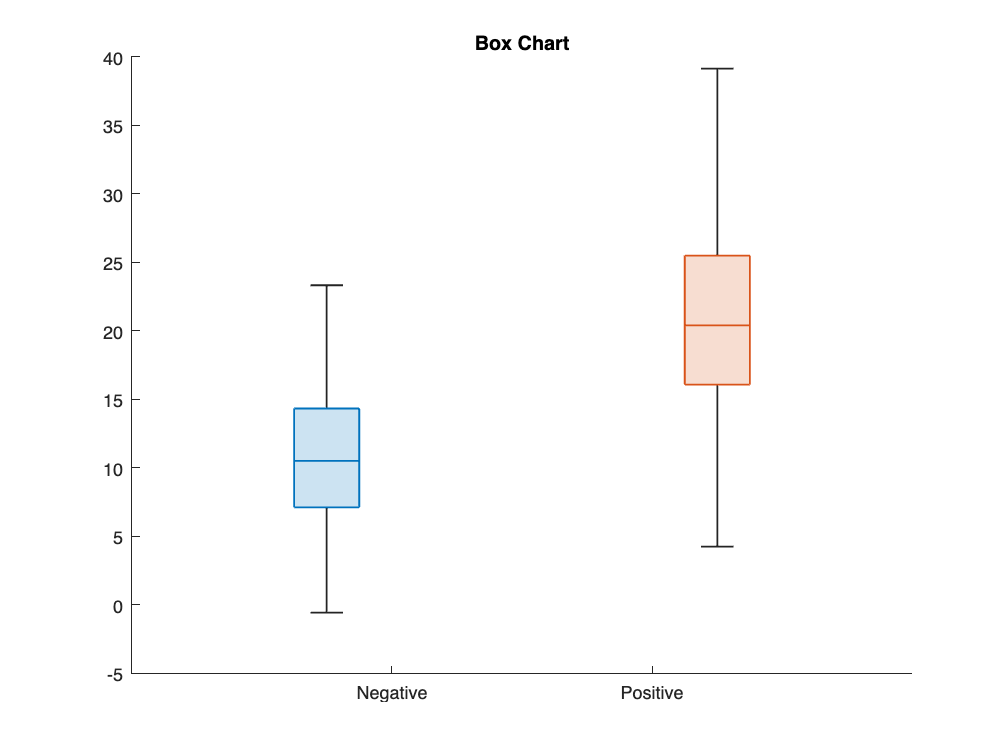

% note in this demo, it is a coincidence the automatic colours of the box chart 
% are what we want.
figure(Name="Box Chart")
x = categorical(referenceStandard,[negClass posClass],{'Negative','Positive'}) ;
b = boxchart(x, scoresTest, 'GroupByColor', referenceStandard) ;
title("Box Chart")

Finally, let's see the histograms of the data. These show the shapes of the distributions of data points in the sample. Again, we can see the overlap region, though the `swarmchart` has the advantage of showing individual data points and not bins.

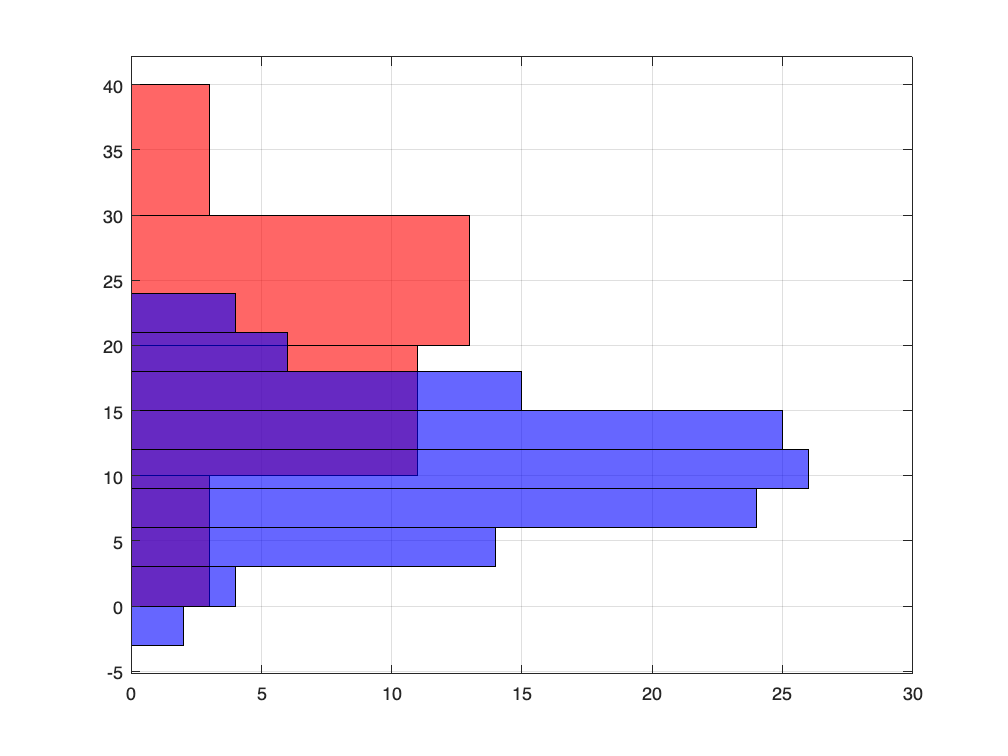

% Show histograms
hPositive = histogram(scoresOfTruePositives,'Orientation','horizontal','FaceColor','r','FaceAlpha',0.6) ;
hold on, grid on
hNegative = histogram(scoresOfTrueNegatives,'Orientation','horizontal','FaceColor','b','FaceAlpha',0.6) ;

From the previous figures, we can see that there is an overlap region where subjects with the same test score can be either true positive or true negative. It is this overlap region that is problematic. The performance of the test at a set score (set threshold) can be characterised by its Sensitiviy and Specificity. The way these change with the threshold can be seen in an ROC curve.

To plot an ROC curve, we can use `perfcurve`.

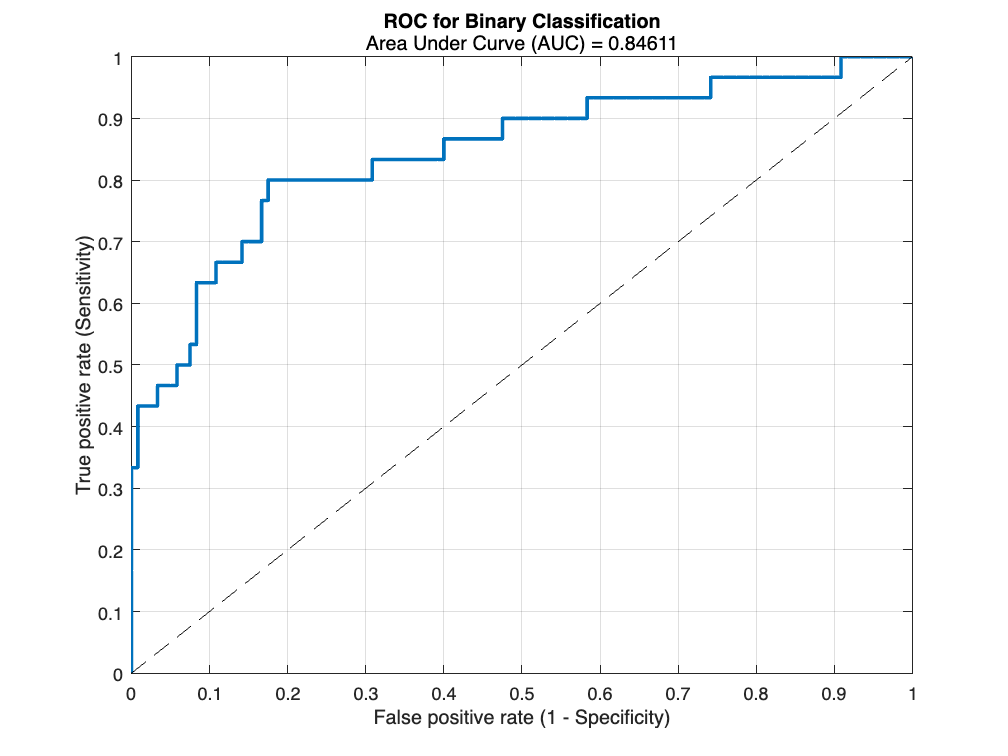

[X,Y,T,AUC,OPTROCPT] = perfcurve(referenceStandard,scoresTest,posClass);
figure
plot(X,Y, LineWidth=2), hold on, grid on
plot([0 1],[0 1],'k--') 
xlabel('False positive rate (1 - Specificity)')
ylabel('True positive rate (Sensitivity)')
title("ROC for Binary Classification","Area Under Curve (AUC) = "+AUC)

Add markers at three different thresholds to highlight that the curved part of the ROC curve depends only on the thresholds where test scores from the true positive and true negative overlap. If there is a small number of points in that region, the ROC curve will have obvious steps, 

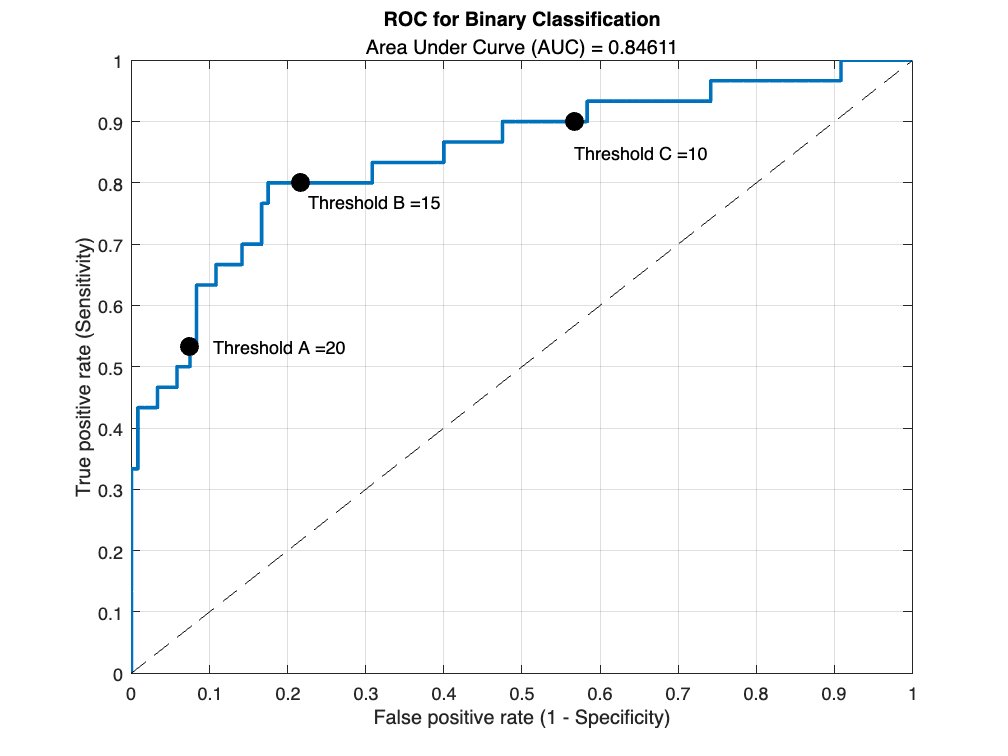

thresholdA = meanTestPositive  ;
thresholdB = ( meanTestNegative + meanTestPositive ) / 2 ;
thresholdC = meanTestNegative  ;

% Find locations of these thresholds on the ROC curve
[~, iThreshA] = min(abs(T-thresholdA)) ; % location of threshold closest to thresholdA
[~, iThreshB] = min(abs(T-thresholdB)) ; 
[~, iThreshC] = min(abs(T-thresholdC)) ; 

markerArgs = { 'MarkerSize',10, 'MarkerEdgeColor','k', 'MarkerFaceColor','k'} ;
plot(X(iThreshA(1)), Y(iThreshA(1)),'ko', markerArgs{:})
text(X(iThreshA(1))+0.03, Y(iThreshA(1)), ['Threshold A =',num2str(thresholdA)])

plot(X(iThreshB(1)), Y(iThreshB(1)),'go',  markerArgs{:})
text(X(iThreshB(1))+0.01, Y(iThreshB(1))-0.03, ['Threshold B =',num2str(thresholdB)])

plot(X(iThreshC(1)), Y(iThreshC(1)),'ro',  markerArgs{:})
text(X(iThreshC(1)), Y(iThreshC(1))-0.05, ['Threshold C =',num2str(thresholdC)])

This simulation script can be re-run many times to give an indication of the variability in the cure shape. In reality, we measure only one sample of limited size. A method to estimate confidence intervals is bootstrapping where an analysis is run multiple times leaving out different permutations of data.

Typically an operting point is chosen and we can assess the variability at that point. In this example, we pick the threshold that gives a Sensitivity closest to 90% as the operating point (i.e. 9 out of 10 positive cases are correctly identified). The choice of operating point depends upon the risks and costs of under or over diagnosis and treatment.

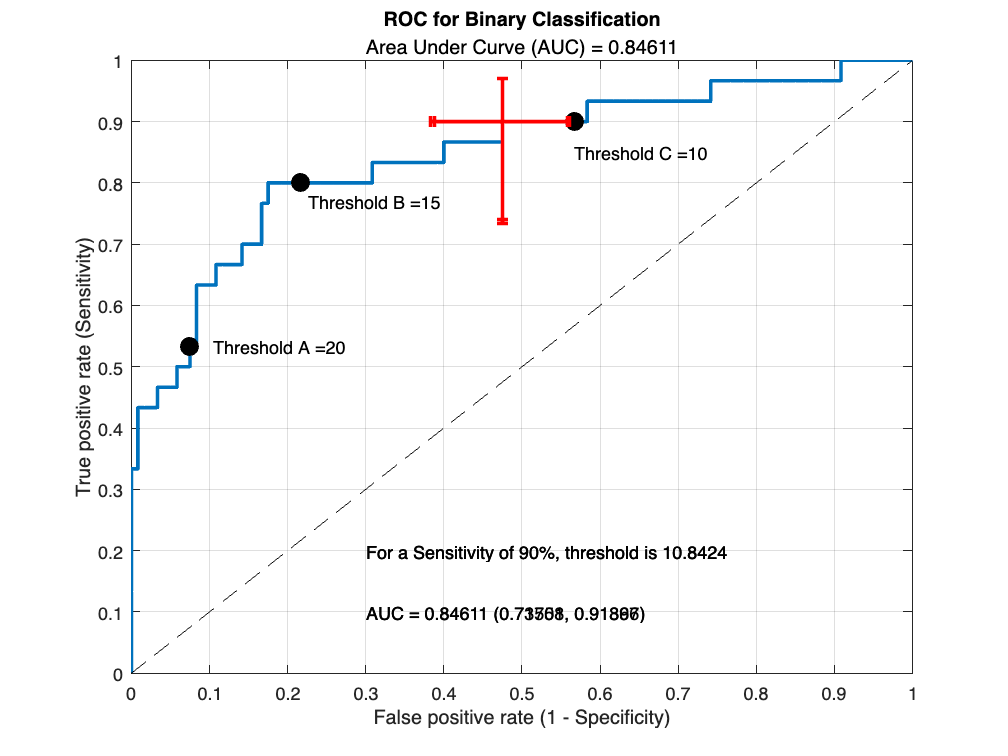

% Use Bootstrapping in perfcurve. Note Xb,Yb and AUCb outputs have 3 columns -
% the value, its lower limit and its upper limit.
[Xb,Yb,Tb,AUCb] = perfcurve(referenceStandard,scoresTest,posClass,'NBoot', 1000);

% Put text information on graph
text(0.3,0.1,"AUC = "+AUCb(1)+" ("+AUCb(2)+", "+AUCb(3)+")")

% At a pre-determined Sensitivity (y value) of 90%
yPreset = 0.9 ;
[~,itpr] = min(abs( Yb(:,1) - yPreset)) ; % itpr is index into true positive rate array Yb

ind = itpr(1) ; % In case there is more than one point equi-distant from yPreset

text(0.3,0.2,"For a Sensitivity of "+Yb(ind,1)*100 +"%, threshold is "+Tb(ind))

% errorbar(x,y,yneg,ypos,xneg,xpos)
eb = errorbar(Xb(ind,1), Yb(ind,1), Yb(ind,1)-Yb(ind,2), Yb(ind,3)-Yb(ind,1), ...
                                    Xb(ind,1)-Xb(ind,2), Xb(ind,3)-Xb(ind,1) ) ;

eb.LineWidth = 2 ; eb.Color = [1 0 0] ;

% Display a table and calculate Sensitivity and Specificty at a set
% threshold
ttable = table('Size',[2 2],'VariableTypes',{'uint64','uint64'},  ...
    'VariableNames',{'True Positive','True Negative'}, ...
    'RowNames',{'Test Positive','Test Negative'}) ;

TTPR90 = Tb(ind) ; % Threshold at which Sensitivity (TPR) is 90% (see above)

% isTP etc are arrays with 0 where expression is false, and 1 where true
isTP = scoresTest >= TTPR90 & referenceStandard==posClass ;
isTN = scoresTest <  TTPR90 & referenceStandard==negClass ;
isFP = scoresTest >= TTPR90 & referenceStandard==negClass ;
isFN = scoresTest <  TTPR90 & referenceStandard==posClass ;

TP = sum(isTP) ; TN = sum(isTN) ; FP = sum(isFP) ; FN = sum(isFN) ;

ttable.("True Positive") = [ TP ; FN ];
ttable.("True Negative") = [ FP ; TN ];

ttable

ttable = 2×2 table
                     True Positive    True Negative
                     _____________    _____________
    Test Positive         27               57      
    Test Negative          3               63      


disp("Sensitivity: TPR = TP/(TP+FN) = " + TP + " / ( " + TP +" + " + FN + " ) = " + TP/(TP+FN))

Sensitivity: TPR = TP/(TP+FN) = 27 / ( 27 + 3 ) = 0.9



disp("Specificity: TNR = 1-FPR = TN/(TN+FP) = " + TN + " / ( " + TN +" + " + FP + " ) = " + TN/(TN+FP))

Specificity: TNR = 1-FPR = TN/(TN+FP) = 63 / ( 63 + 57 ) = 0.525


Re-plot the swarmchart with the above threshold as a horizontal line.

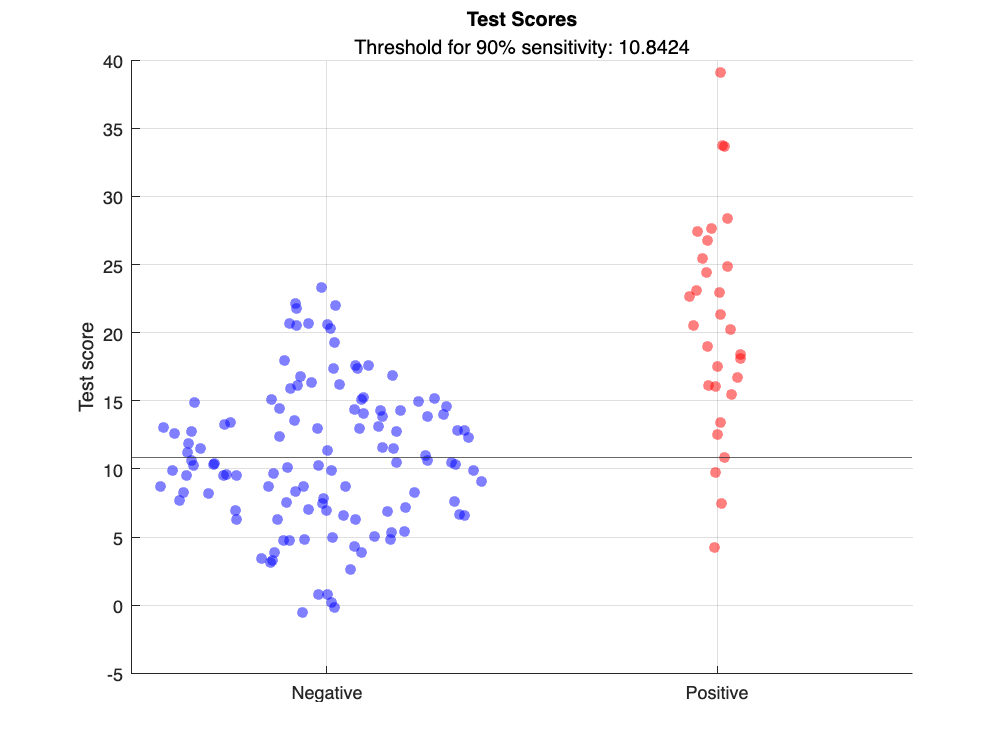

figure(Name='swarmchart Test Scores')
swarmchart(referenceStandard, scoresTest, [], refColours, 'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
title("Test Scores", "Threshold for 90% sensitivity: "+TTPR90)
ylabel('Test score')
xticks([negClass posClass]), xticklabels({'Negative','Positive'})
grid on

yl = yline(TTPR90) ;

Note because we specified a high sensitivity of 90%, the threshold is "forced" down so that most of the red (positive) points are above the threshold. The lower the threshold, the more true negatives get incorrectly called as positve (blue points above the line). 

*David Atkinson, 2023.*